# 02686 - Scientific Computing for Differential Equations - Exam 

## 6 - Dormand-Prince 5

## Dormand-Prince 5

mu = 3;
mu2 = 20;
x0 = [1.0;1.0];
N = 10000;
t0 = 0; tf = 50;

[T,X] = dopri54FixedStepSize(@VanDerPol,0,tf,N,x0,mu);
[T1,X1] = dopri54FixedStepSize(@VanDerPol,0,tf,N,x0,mu2);

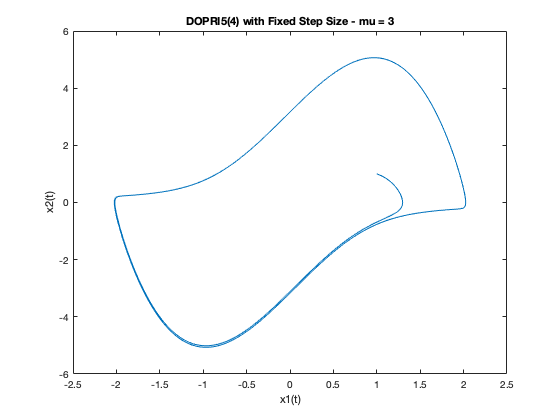

plot(X(:,1),X(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('DOPRI5(4) with Fixed Step Size - mu = 3')

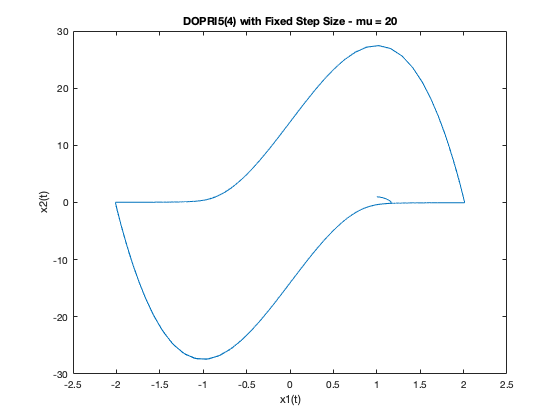


plot(X1(:,1),X1(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('DOPRI5(4) with Fixed Step Size - mu = 20')

## For test equation

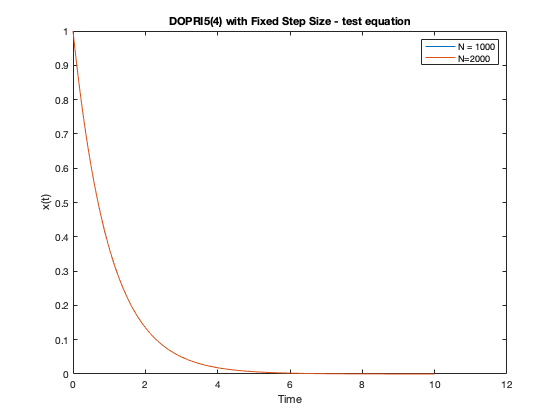

mu = 3;
mu2 = 20;
x0 = 1.0;

N = 1000;
N2 = 2000;

T_final = 10;
[T,X] = dopri54FixedStepSize(@testEquationJac,0,T_final,N,x0,mu);
[T1,X1] = dopri54FixedStepSize(@testEquationJac,0,T_final,N2,x0,mu);

plot(T,X)
hold on 
plot(T1,X1)
hold off
xlabel('Time')
ylabel('x(t)')
title('DOPRI5(4) with Fixed Step Size - test equation')
legend('N = 1000','N=2000')

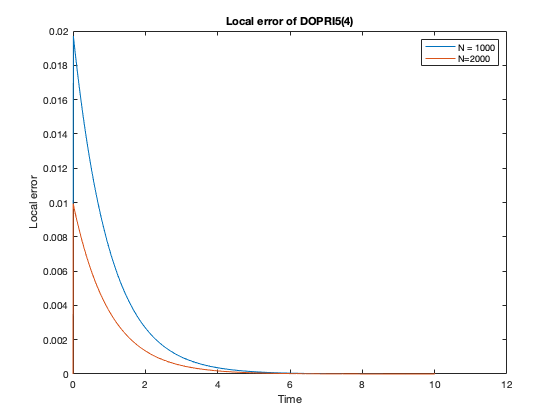

% Local and global truncation errors
l = local_error(T,X);
l1 = local_error(T1,X1);
plot(T,l);
hold on
plot(T1,l1);
title("Local error of DOPRI5(4)");
xlabel("Time");
ylabel("Local error");
legend('N = 1000','N=2000')

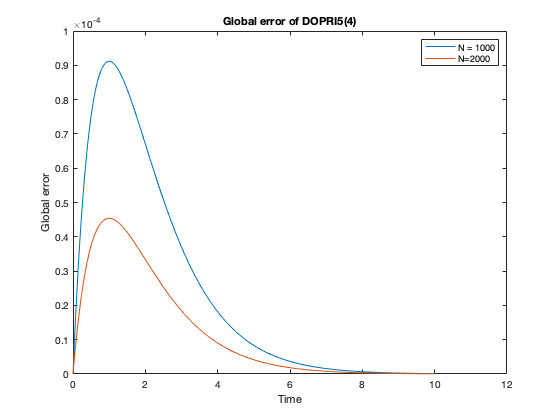

g = global_error(T,X);
g1 = global_error(T1,X1);
plot(T,g);
hold on
plot(T1,g1)
hold off
title("Global error of DOPRI5(4)");
legend('N = 1000','N=2000')
xlabel("Time");
ylabel("Global error");

## DOPRI5(4) with Adaptative Step Size

mu = 3;
mu2 = 20;
x0 = [1.0;1.0];
N = 15000;
t0 = 0; tf = 50;

abstol = 1e-7;
reltol = 1e-7;

[T,X,info] = dopri54AdaptativeStepSize(@VanDerPol,0,tf,x0,N,abstol,reltol,mu);
[T1,X1,info1] = dopri54AdaptativeStepSize(@VanDerPol,0,tf,x0,N,abstol,reltol,mu2);

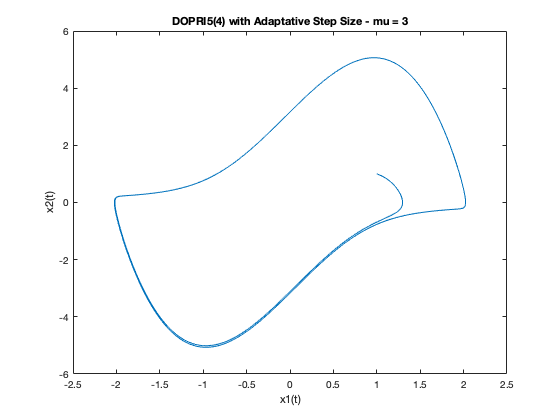

plot(X(:,1),X(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('DOPRI5(4) with Adaptative Step Size - mu = 3')

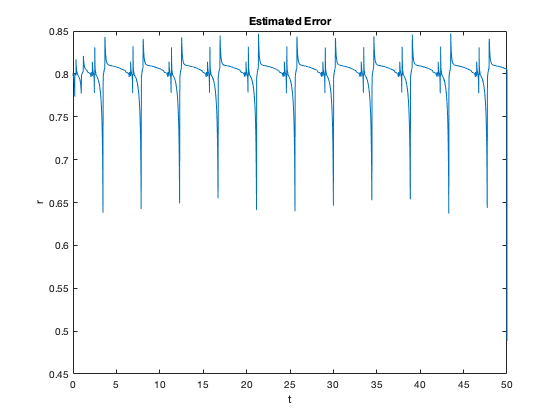


n = length(T);

plot(T(2:n),info.rr)
xlabel("t")
ylabel("r")
title("Estimated Error")

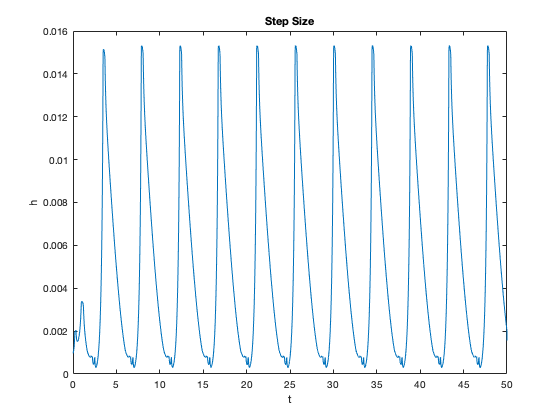


plot(T(2:n),info.hh)
xlabel("t")
ylabel("h")
title("Step Size")

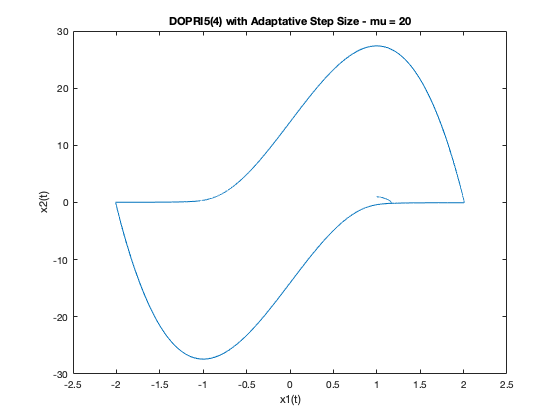

plot(X1(:,1),X1(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('DOPRI5(4) with Adaptative Step Size - mu = 20')

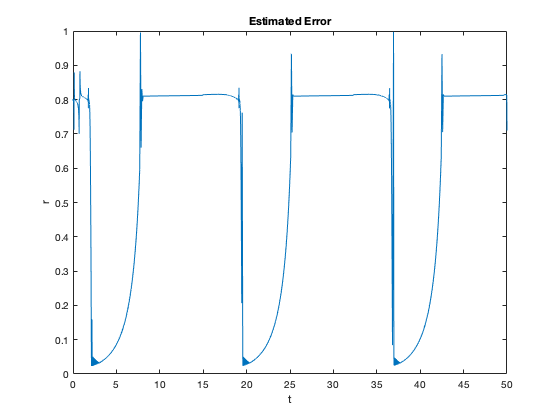


n = length(T1);

plot(T1(2:n),info1.rr)
xlabel("t")
ylabel("r")
title("Estimated Error")

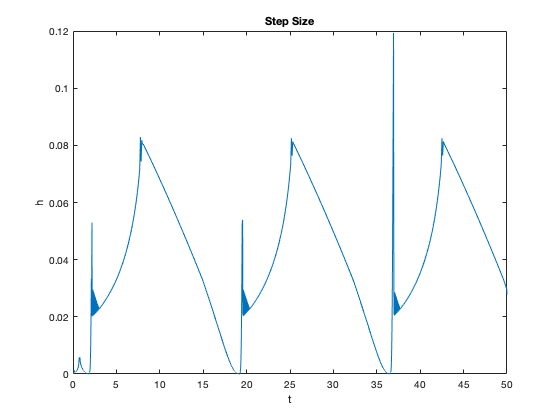


plot(T1(2:n),info1.hh)
xlabel("t")
ylabel("h")
title("Step Size")

## Solver ODE45,ODE15,DOPRI5(4)

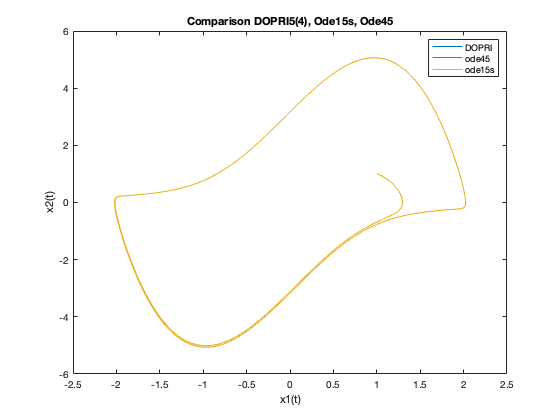

mu = 3;
x0 = [1.0; 1.0];
t0 = 0; tf = 50;

[T,X,info] = dopri54AdaptativeStepSize(@VanDerPol,t0,tf,x0,N,abstol,reltol,mu);
plot(X(:,1),X(:,2))
hold on 
options = odeset('RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X2]=ode45(@VanDerPol,[t0 tf],x0,options,mu);
plot(X2(:,1),X2(:,2))
hold on 
options = odeset('Jacobian',@JacVanDerPol,'RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X3]=ode15s(@VanDerPol,[t0 tf],x0,options,mu);
plot(X3(:,1),X3(:,2))
hold off
xlabel('x1(t)')
ylabel('x2(t)')
title('Comparison DOPRI5(4), Ode15s, Ode45')
legend('DOPRI','ode45','ode15s')

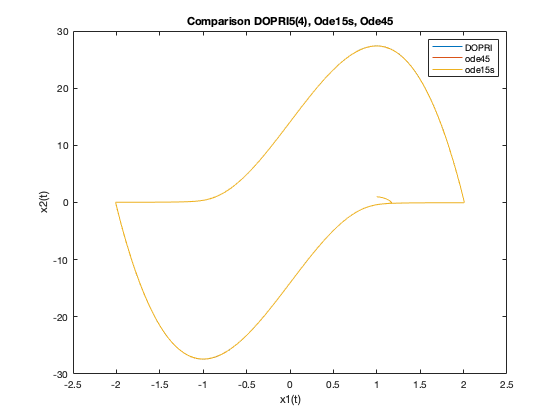

mu = 20;
x0 = [1.0; 1.0];
t0 = 0; tf = 50;

[T,X,info] = dopri54AdaptativeStepSize(@VanDerPol,t0,tf,x0,N,abstol,reltol,mu);
plot(X(:,1),X(:,2))
hold on 
options = odeset('RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X2]=ode45(@VanDerPol,[t0 tf],x0,options,mu);
plot(X2(:,1),X2(:,2))
hold on 
options = odeset('Jacobian',@JacVanDerPol,'RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X3]=ode15s(@VanDerPol,[t0 tf],x0,options,mu);
plot(X3(:,1),X3(:,2))
hold off
xlabel('x1(t)')
ylabel('x2(t)')
title('Comparison DOPRI5(4), Ode15s, Ode45')
legend('DOPRI','ode45','ode15s')

# CSTR problem

## 1-Dimensional

abstol = 1e-7;
reltol = 1e-7;

% Parameters
rho = 1.0;      % density
cp = 4.186;      % specific heat capacity
k0 = 4.8266*(10^10); % Arrhenius constant
EaR = 8500;     % Activation Energy
delHr = -560;   % Reaction enthalpy
V = 1.0;      % Reactor Volume
CAin = 0.8;   % Inlet Concentration of A
CBin = 1.6;   % Inlet Concentration of B
Tin = 273.65;       % Inlet Temperature

p = [rho; cp; k0; EaR; delHr; V; CAin; CBin; Tin];

x0 = 0; % Initial Temperature
t0 = 0; 
T_final = 35; 

u = 0.5; % Flow Rate
[T,X1,info] = dopri54AdaptativeStepSizeCSTR(@CSTR1d,0,T_final,u,x0,abstol,reltol,p);
% u = 0.2; % Flow Rate
% [T,X2,info] = dopri54AdaptativeStepSizeCSTR(@CSTR1d,0,T_final,u,x0,abstol,reltol,p);
% u = 0.7; % Flow Rate
% [T,X3,info] = dopri54AdaptativeStepSizeCSTR(@CSTR1d,0,T_final,u,x0,abstol,reltol,p);

beta = -delHr/(rho*cp);
% X1 is a List of temperature 
% We compute the extent of reaction B = (X)
X1_true = -(2*(x0-X1))/(beta*CBin);
plot(T,X1_true)
xlabel('time')
ylabel('Extent of reaction')
title('Extent of reaction over time')

plot(T,X1)
hold on;
plot(T,X2)
hold on;
plot(T,X3)
hold off;
title("");
xlabel("Time");
legend("0.5","0.2","0.7");

## 3D Dimensional

% Parameters
rho = 1.0;      % density
cp = 4.186;      % specific heat capacity
k0 = 4.8266*(10^10); % Arrhenius constant
EaR = 8500;     % Activation Energy
delHr = -560;   % Reaction enthalpy
V = 0.1;      % Reactor Volume
CAin = 0.8;   % Inlet Concentration of A
CBin = 1.2;   % Inlet Concentration of B
Tin = 273.65;       % Inlet Temperature

p = [rho; cp; k0; EaR; delHr; V; CAin; CBin; Tin];
x0 = [1 1 1]';
N = 10000;
T_final = 4;
u = 0.5;

[T,X1] = dopri54FixedStepSize(@CSTR3d,0,T_final,N,x0,u,p);

plot(T,X1(:,1),"k")
hold on;
plot(T,X1(:,2),"--b")
hold on;
plot(T,X1(:,3),":r")
hold off
legend("1","2","3")

plot(T,X1(:,1))



plot(T,X1(:,2))


plot(T,X1(:,3))
